# Lab 5 - Least Squares

## Problem 1

function [result] = MyLinearSystem(xs,gs)
    A = []
    i = 0
    while i < length(gs)
        g = gs{i + 1}
        A = [A g(xs)]
        i = i + 1
    end
    
    A = [ones(length(xs),1) A]
    result = A
end

## Problem 2

function [result] = MyLeastSquares(A,v)
   As = transpose(A);
   Ap = As * A;
   vp = As * v;
   F = [Ap vp];
   result = rref(F);
end

## Problem 3

Full function:

A = MyLinearSystem(xs,gs);
u = MyLeastSquares(A,v);


%This is all for plotting
xaxis = -2:1/100:7;
y = 0;
i = 0;
while i < length(gs)
    g = gs{i + 1};
    y = y + (u(i+2,length(gs) + 2))*g(xaxis);
    i = i + 1;
end
y = u(1,length(gs) + 2) + y;
plot(xaxis,y)
hold on
scatter(xs,v)
hold off
%End of plotting

%Sum of Squares of Error
i = 0;
S = [u(1,length(gs) + 2).*A(:,1)];
while i < length(gs)
    S = [S u(i+2,length(gs) + 2).*A(:,i+2)];
    i = i + 1;
end
i = 0;
SS = [zeros(length(xs),1)]
while i < length(gs) + 1
    SS = [SS+S(:,i+1)];
    i = i + 1;
end
E = [(v-SS).^2];
SumOfSquaresOfError = sum(E,'all')
%End

function [result] = MyLinearSystem(xs,gs)
    A = [];
    i = 0;
    while i < length(gs)
        g = gs{i + 1};
        A = [A g(xs)];
        i = i + 1;
    end
    
    A = [ones(length(xs),1) A];
    result = A;
end

function [result] = MyLeastSquares(A,v)
   As = transpose(A);
   Ap = As * A;
   vp = As * v;
   F = [Ap vp];
   result = rref(F)
end

### a)

SumOfSquaresOfError =

    5.4230

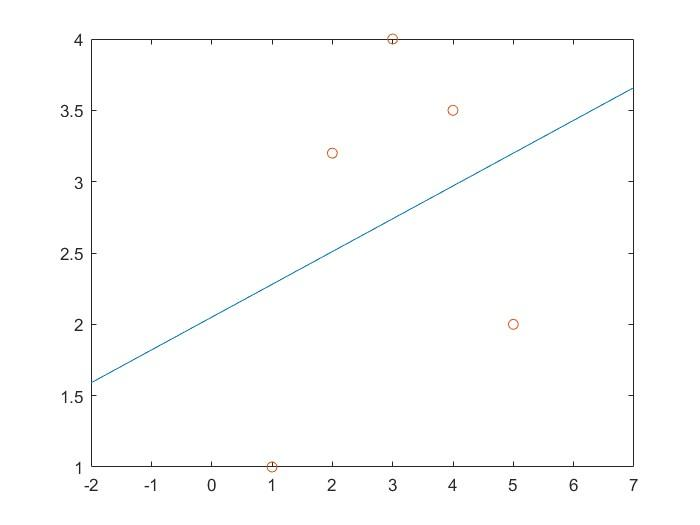

### b)

SumOfSquaresOfError =

    0.0166  

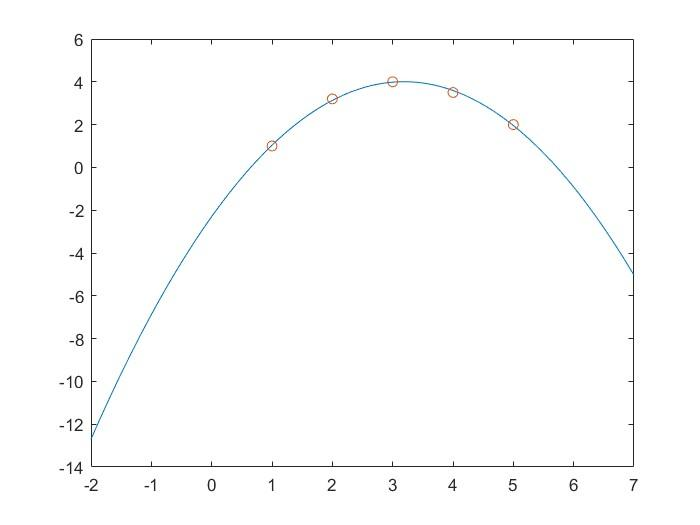

**C)**

SumOfSquaresOfError =

   1.6340e-05

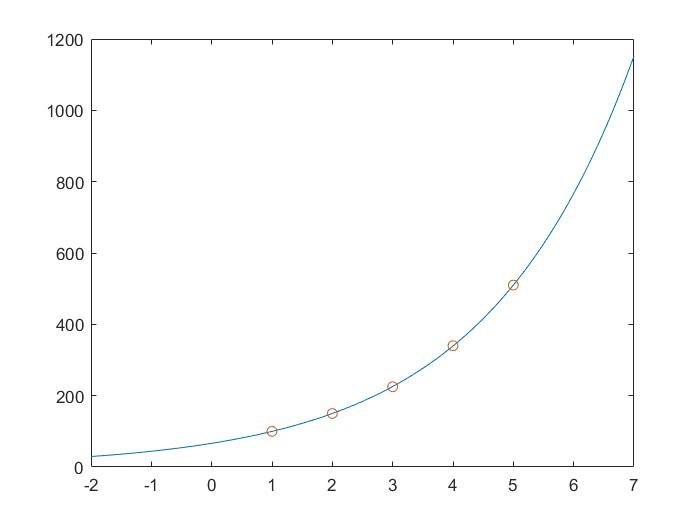

**D)**

Part a was very bad, while b and c both seemed to use a function that fit the data very well.

## Problem 4

Below are the curves for the equation given to us, and the second curve is the same equation but the period of the trig functions has been altered slightly to produce a better fit, it's the one with the lower Sum of Squares of Error

SumOfSquaresOfError =

   15.7754

SumOfSquaresOfError =

    8.6092